# Breathing rate alarm - Analog electronics

Copyright (C) [2020](#2020)  [Bolic](#Miodrag)

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES.

### Acknowledgements: 

## Introduction

In this section, we will present the circuit that detects that the cesation of breathing over 10 sec and produces the alarm at the output. The alarm will be set as a logic from 10 sec onwards after the breathing ceasation is detected.

## Processing in analog electronics

Pulse detector circuit  converts amplified and filtered breathing signals into pulses. The  threshold of the comparator is set to 0.5 V. When the output of the  comparator is one, the capacitor C_1 is connected to the ground through  the voltage controlled switch PS and discharged. During the periods of  logic zero which correspond to the low breathing amplitudes or no  breathing signal, the capacitor is charged. The time constant is  selected to be 10 sec ( and  ). Therefore, the output of the integrator is compared against the fixed  threshold at 0.63 * 5 V = 3.15 V and it generates alarm when the signal  is above the threshold. This threshold is selected like that because it  is known that the voltage of the output of the RC circuit will achieve  0.63 of its maximum at the time that corresponds to the time constant. 

The analog circuit is shown below.

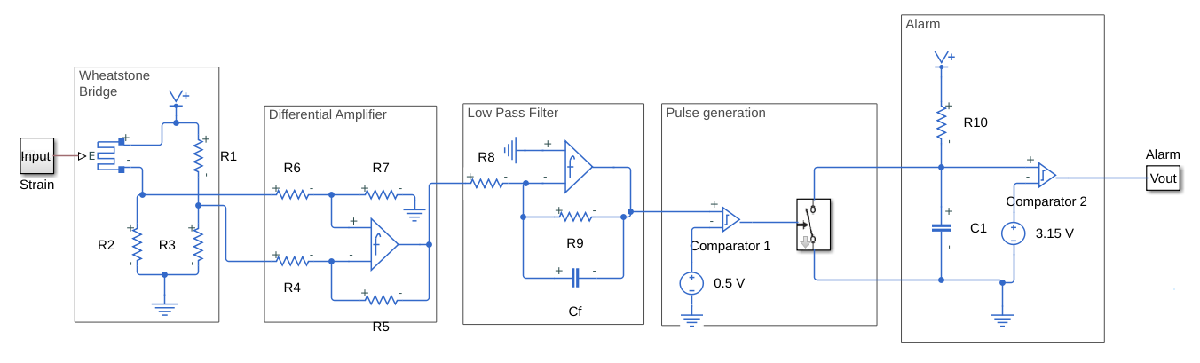

% Simulation
model_name = 'breathing_rate_analog1';
open_system(model_name)
simOut = sim(model_name, 'CaptureErrors', 'on');

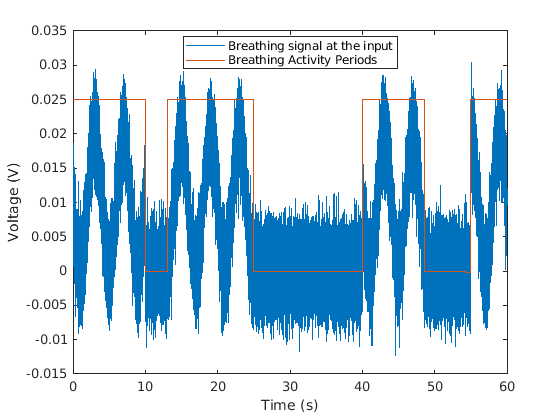

% Plotting results
figure
plot(simOut.S_Noise_in.Time,simOut.S_Noise_in.Data)
hold on
plot(simOut.Activity_in.Time,simOut.Activity_in.Data/40)
xlabel("Time (s)")
ylabel("Voltage (V)")
legend({'Breathing signal at the input', 'Breathing Activity Periods'},'Location','Best')

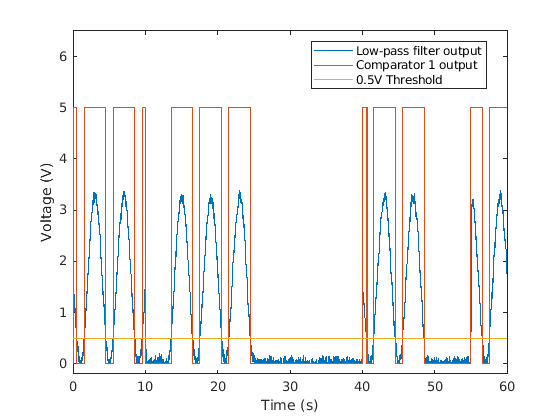


figure
plot(simOut.LPF_out.Time,simOut.LPF_out.Data)
hold on
plot(simOut.Cmp1_out.Time,simOut.Cmp1_out.Data)
plot(simOut.LPF_out.Time,0.5*ones(1,length(simOut.LPF_out.Data)));
xlabel("Time (s)")
ylabel("Voltage (V)")
legend({'Low-pass filter output','Comparator 1 output', '0.5V Threshold'},'Location','Best')
ylim([-0.2, 6.5])

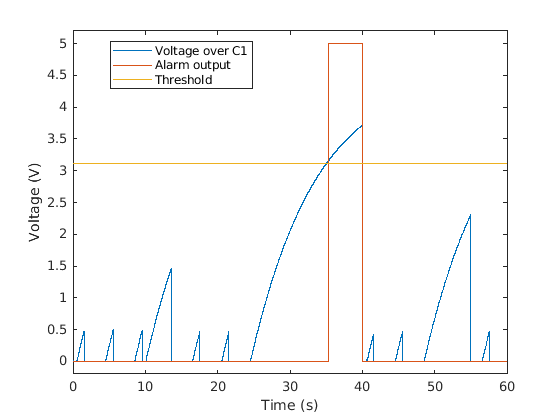


figure
plot(simOut.PG_out.Time,simOut.PG_out.Data)
hold on
plot(simOut.Alarm_out.Time,simOut.Alarm_out.Data)
plot(simOut.LPF_out.Time,3.12*ones(1,length(simOut.LPF_out.Data)));
xlabel("Time (s)")
ylabel("Voltage (V)")
legend({'Voltage over C1', 'Alarm output', 'Threshold'},'Location','Best')
ylim([-0.2, 5.2])

## Processing in software

The major difference is  that analog electronics for detecting stop breathing is replaced with  the anti-aliasing filter, A/D converter and the processor. Processor is  modeled as a Matlab code. It processes data in real time and shows the  result if the alarm if the breathing signal is below a certain threshold for more than 10 sec if the parameter if the circtuit called AVERAGING is set to 0. A/D convertor is selected to have 12 bits and  sampling rate of 80 Hz. 

Anti-aliasing filter is designed to have cutoff frequency of fc=10 Hz. C11=C21= 800  nF, R11= R21 = 10 kOhm. This means that 60 Hz is attenuated by 23 dB.

 The algorithm is implemented to perform the following:

·          Store data that arrives from the A/D converter sequentially

·          Scales data back in the range from 0 V to 5 V

·          Compare last 10 seconds of data with a fixed threshold and if the output is smaller than the threshold, generate the alarm when AVERAGING parameter in the block "alarm" is set to zero.

The circuit is shown below:

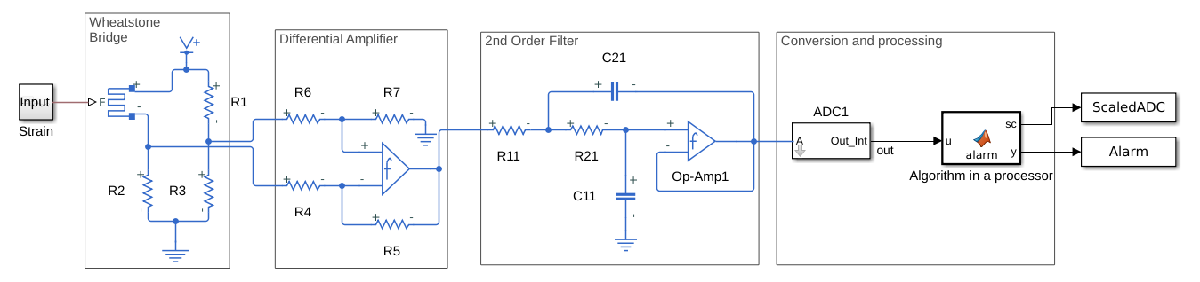

clear all
% Simulation - to change algorithms in the block "alarm" click on the block
% and change AVARAGE from 0 to 1 (or 1 to 0).
% AVERAGING =0 means that the algorithm is based on comparing the 10 sec of
% the signal aganst the threshold
% AVERAGING =1 means that the 10 seconds of the signal is averaged and
% compared against the threshold.
model_name = 'breathing_rate_adc1';
open_system(model_name)
simOut = sim(model_name, 'CaptureErrors', 'on');

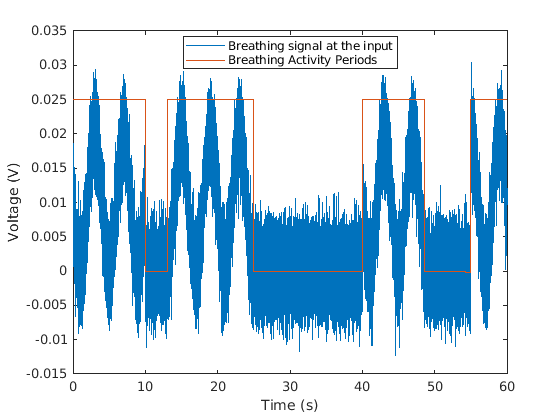

% Plotting results
figure
plot(simOut.S_Noise_in.Time,simOut.S_Noise_in.Data)
hold on
plot(simOut.Activity_in.Time,simOut.Activity_in.Data/40)
xlabel("Time (s)")
ylabel("Voltage (V)")
legend({'Breathing signal at the input', 'Breathing Activity Periods'},'Location','Best')

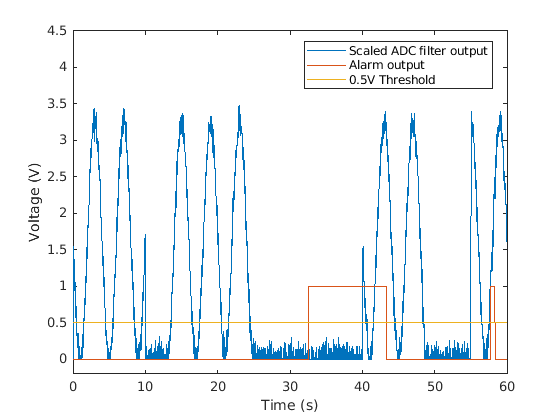


figure
plot(simOut.sc_out.Time,simOut.sc_out.Data)
hold on
plot(simOut.y_out.Time,simOut.y_out.Data)
plot(simOut.y_out.Time,0.5*ones(1,length(simOut.y_out.Data)));
xlabel("Time (s)")
ylabel("Voltage (V)")
legend({'Scaled ADC filter output', 'Alarm output', '0.5V Threshold'},'Location','Best')
ylim([-0.2, 4.5])

**Excersize**:  In order to simulate effect of aliasing as well  as anti-aliasing filter, add 60 Hz interference as well at the  input. Observe the effects of alliasing at the output.

**Excersize**:  Add motion artifact in the duration of 1 sec. The artifact should result in the signal amplitude larger than 1 V. Make sure that the motion artifact accurs during the 15 sec stop breathing intervals. Compare the outputs of the algorithms with and without averaging.